s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Plant transfer function.

G = 100/(s*(s+1)*(s+10))

G =
 
          100
  -------------------
  s^3 + 11 s^2 + 10 s
 
Continuous-time transfer function.



Calculate the phase of the system at 5 rad/s to add a lead compensator.

[mag,phase,wout,sdmag,sdphase] = bode(G,5)

mag = 0.3508

phase = -195.2551

wout = 5


sdmag =

     []


sdphase =

     []



Lead compensator transfer function is now obtained which will provide the desired phase margin. 

K = lead(75.2251,5)

K =
 
  s + 0.6483
  ----------
  s + 38.56
 
Continuous-time transfer function.



New transfer function is now obtained which has the desired phase margin. 

L = K*G/0.0455

L =
 
                 100 s + 64.83
  --------------------------------------------
  0.0455 s^4 + 2.255 s^3 + 19.76 s^2 + 17.55 s
 
Continuous-time transfer function.



Next, we calculate the magnitude at the desired cross-over frequency to provide an offset to the magnitude plot to achive the desired preformance.

[mag,phase,wout,sdmag,sdphase] = bode(L,5)

mag = 0.9997

phase = -120.0300

wout = 5


sdmag =

     []


sdphase =

     []



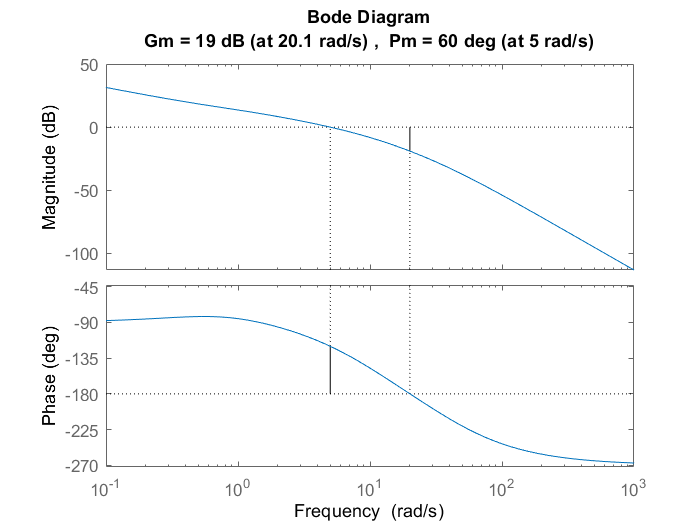

margin(L)

Step response of the closed loop system.

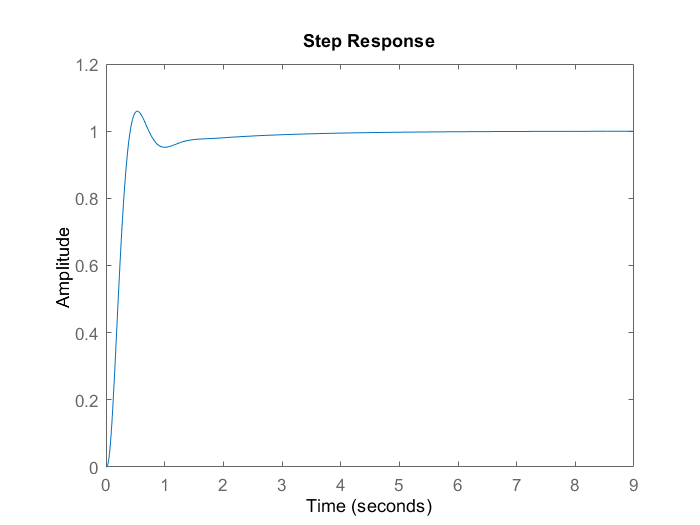

step(L/(L+1))